# Lysosome Display and Statistical Analysis

## Load Required Variables

clearvars -except paths proj
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths);
idT = sortrows(idT,["Type", "Health"]);

### Type I

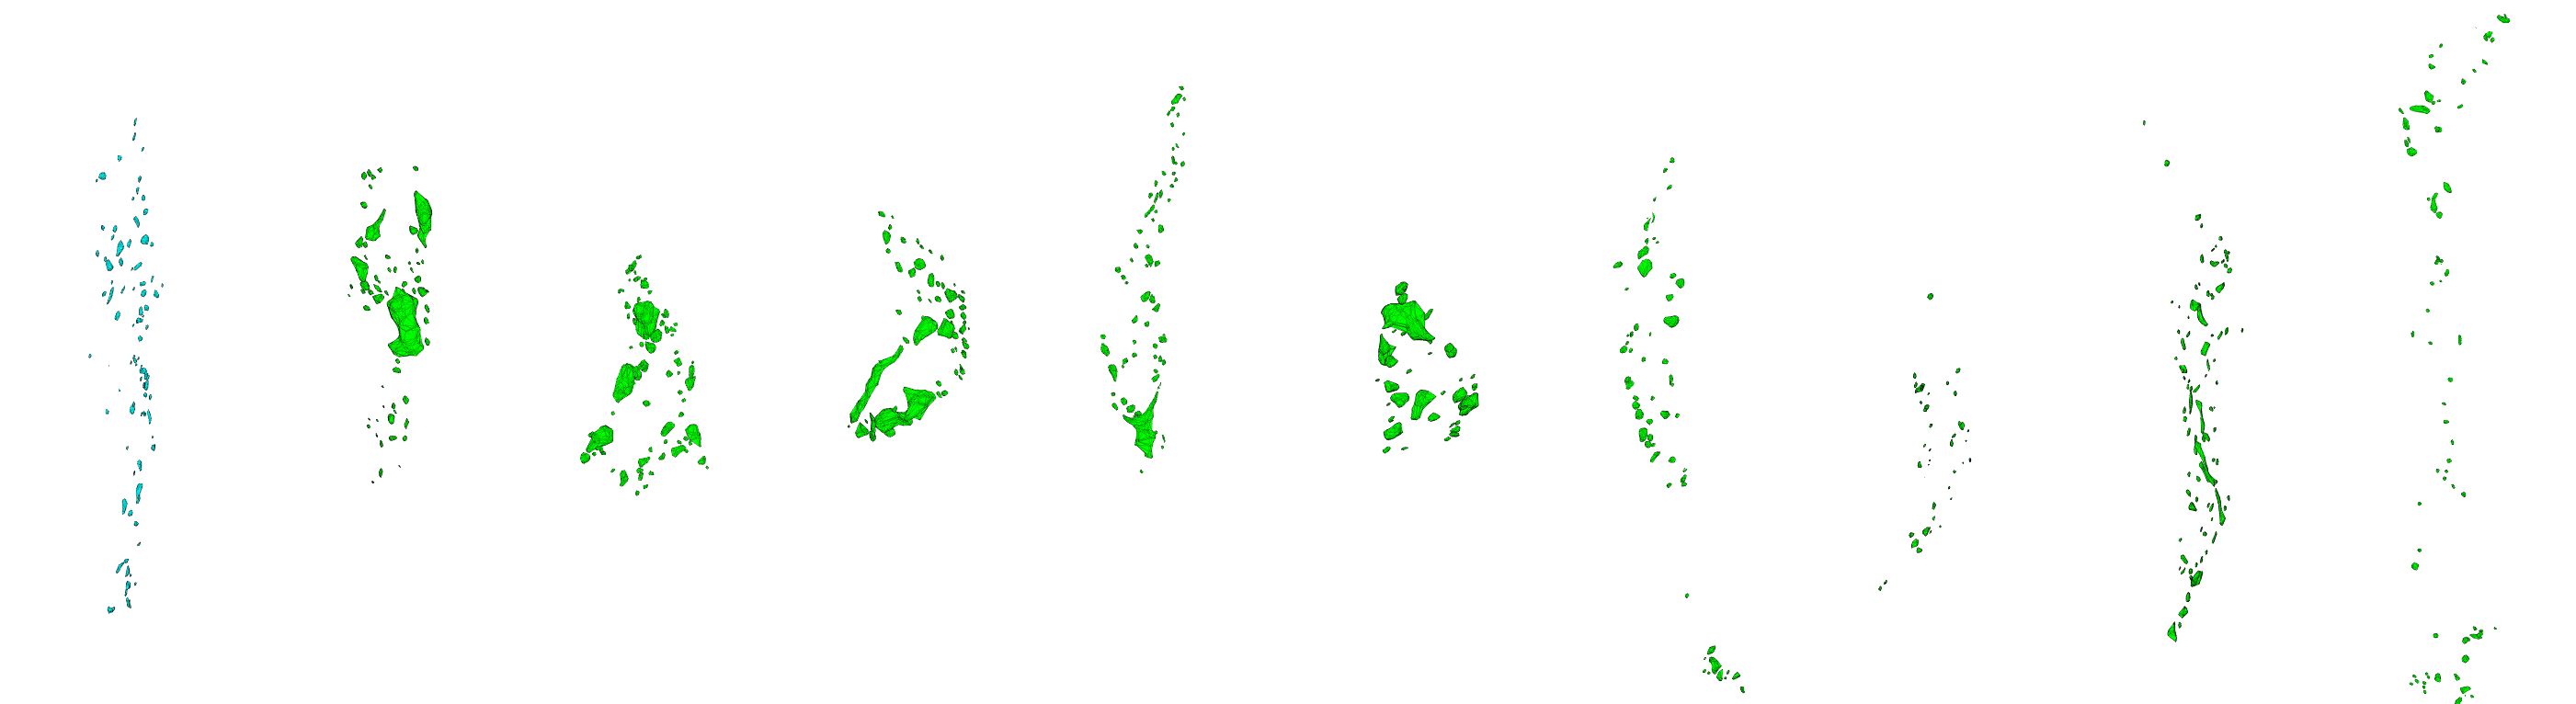

ax = plot_lys_alphaSurface(VL, idT, "I");

### Type II

11. TB1_AP13_EM. early. 12. TB1_AP40_EM. early. 13. TB1_AP51_EM. early. 14. TB2_T2C-01_FR. early. 15. TB2_T2C-03_cw. early. 16. TB1_AP14_EM. healthy. 17. TB2_T2C-09_cw. healthy. 18. TB2_T2C-10_cw. healthy. 19. TB2_T2C-12_cw. healthy. 20. TB2_T2Cell03_CM_LES. healthy. 

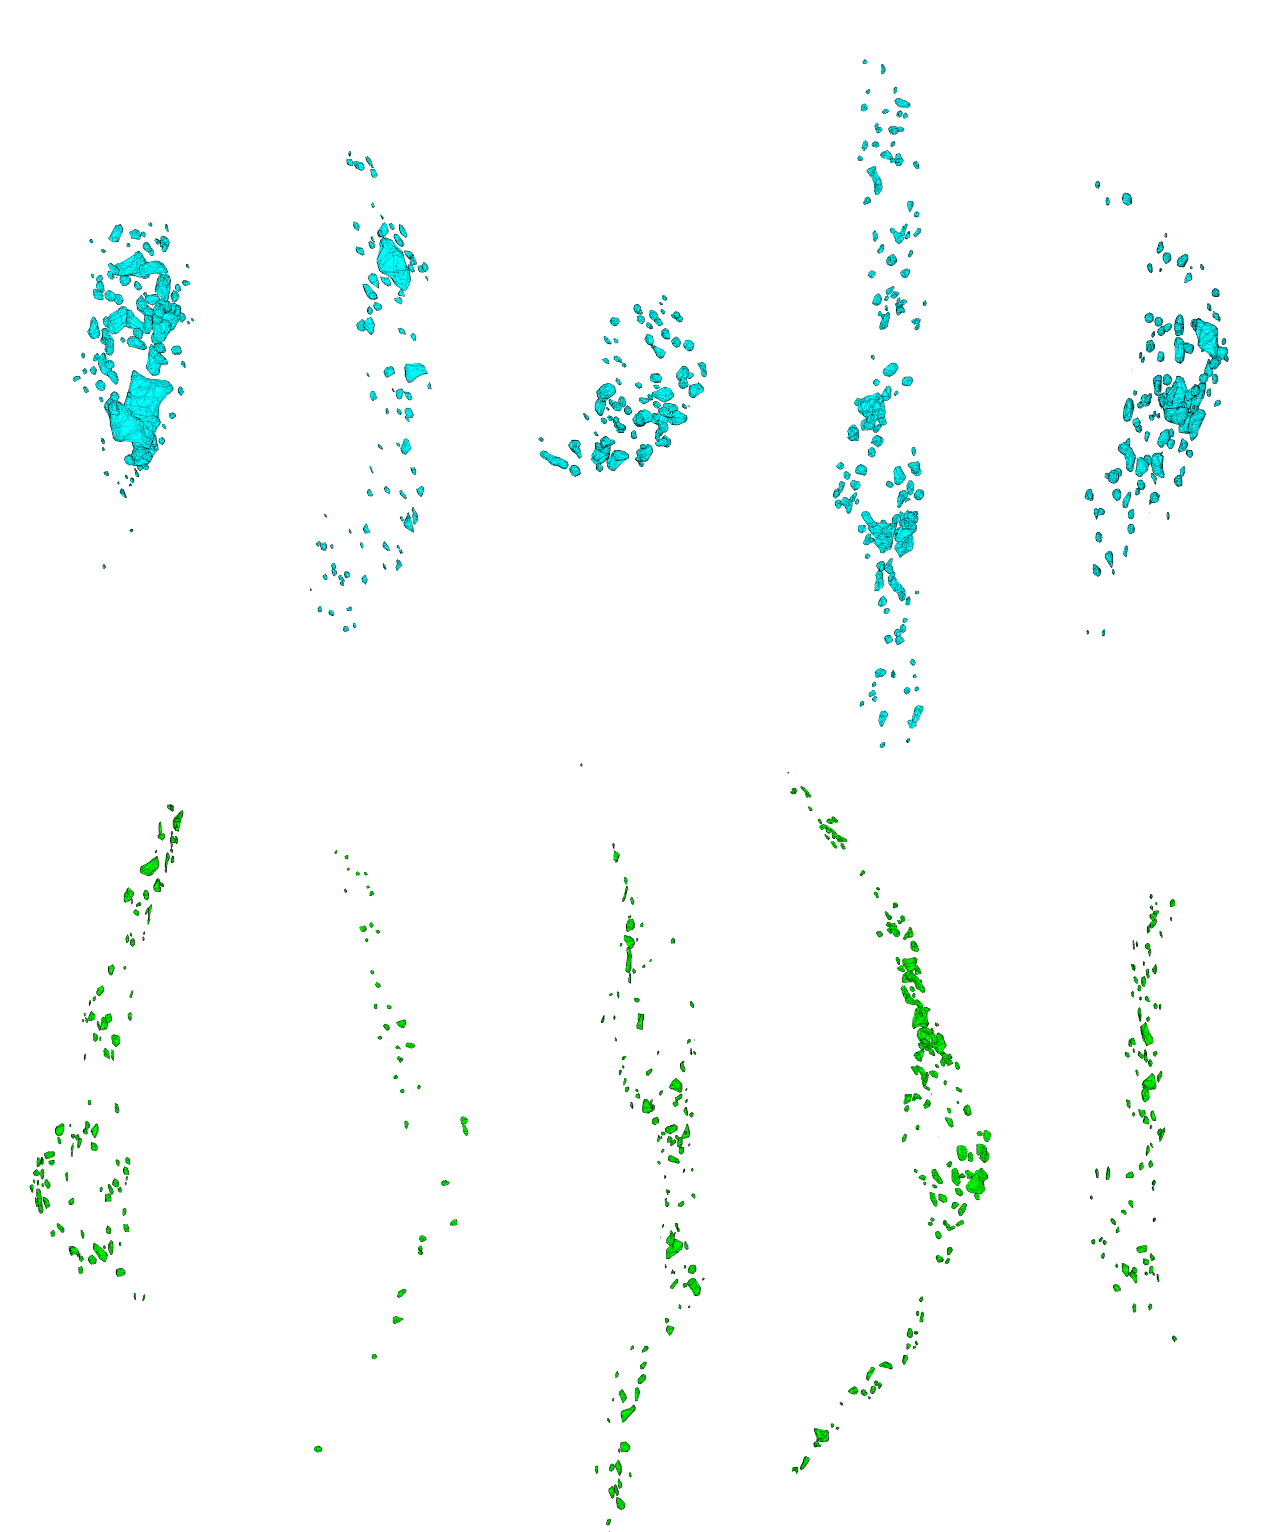

ax2 = plot_lys_alphaSurface(VL, idT, "II");

### Type III

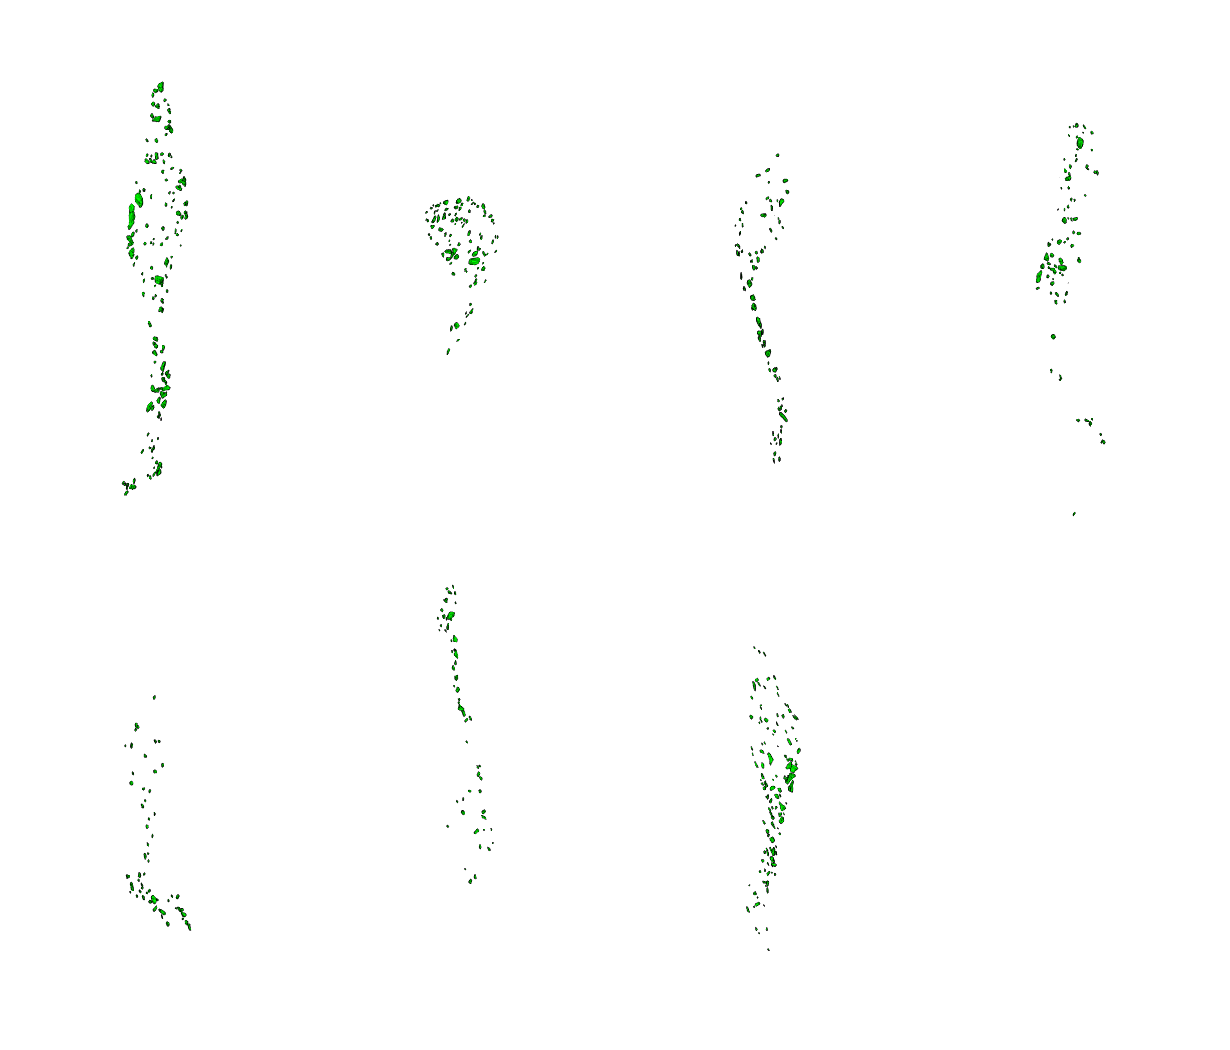

ax3 = plot_lys_alphaSurface(VL, idT, "III");

### Type 4

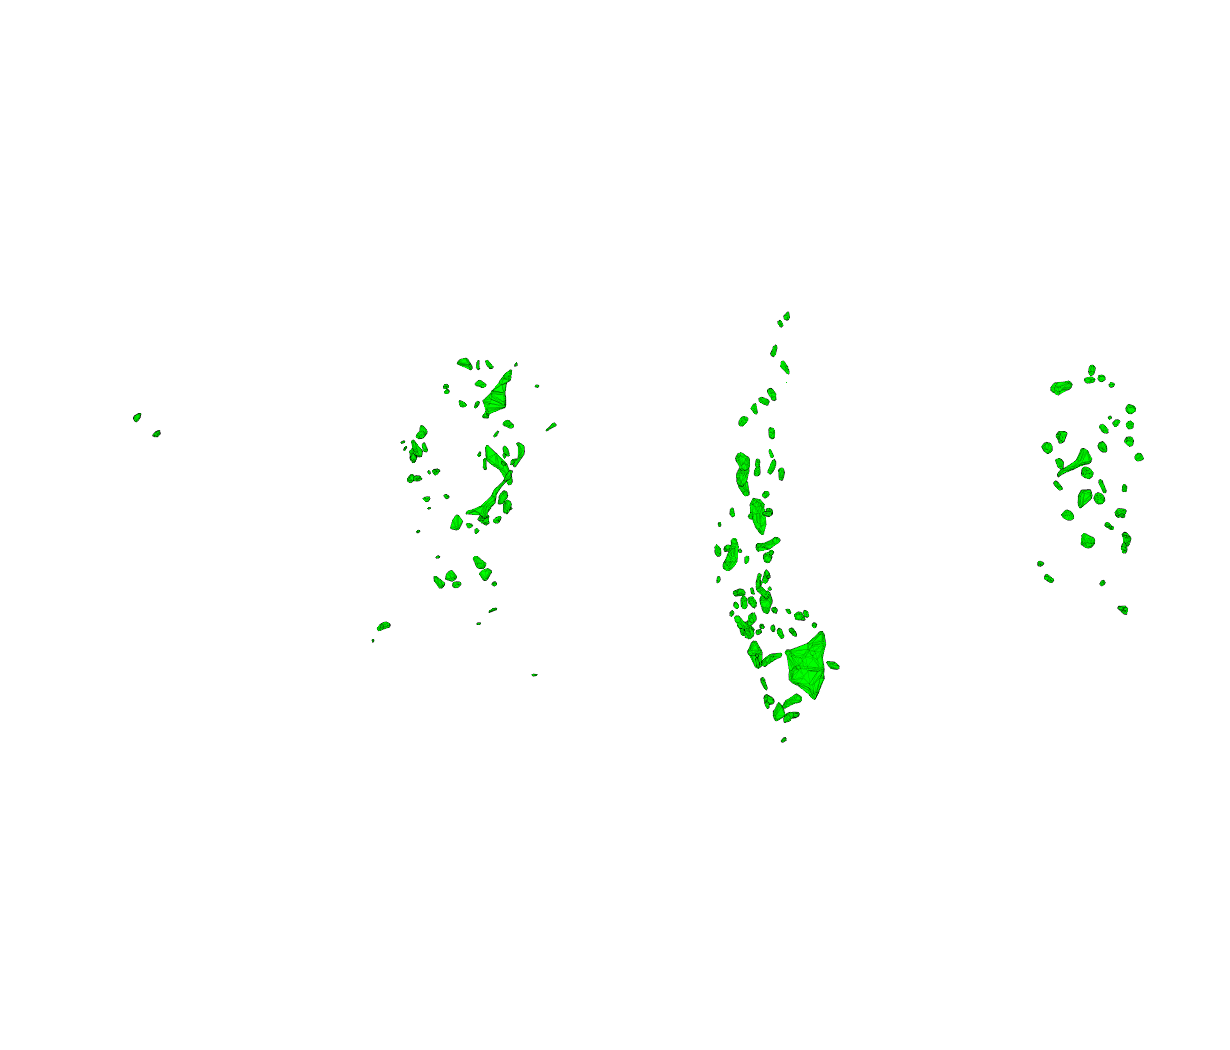

ax4 = plot_lys_alphaSurface(VL, idT, "IV");

### Type X

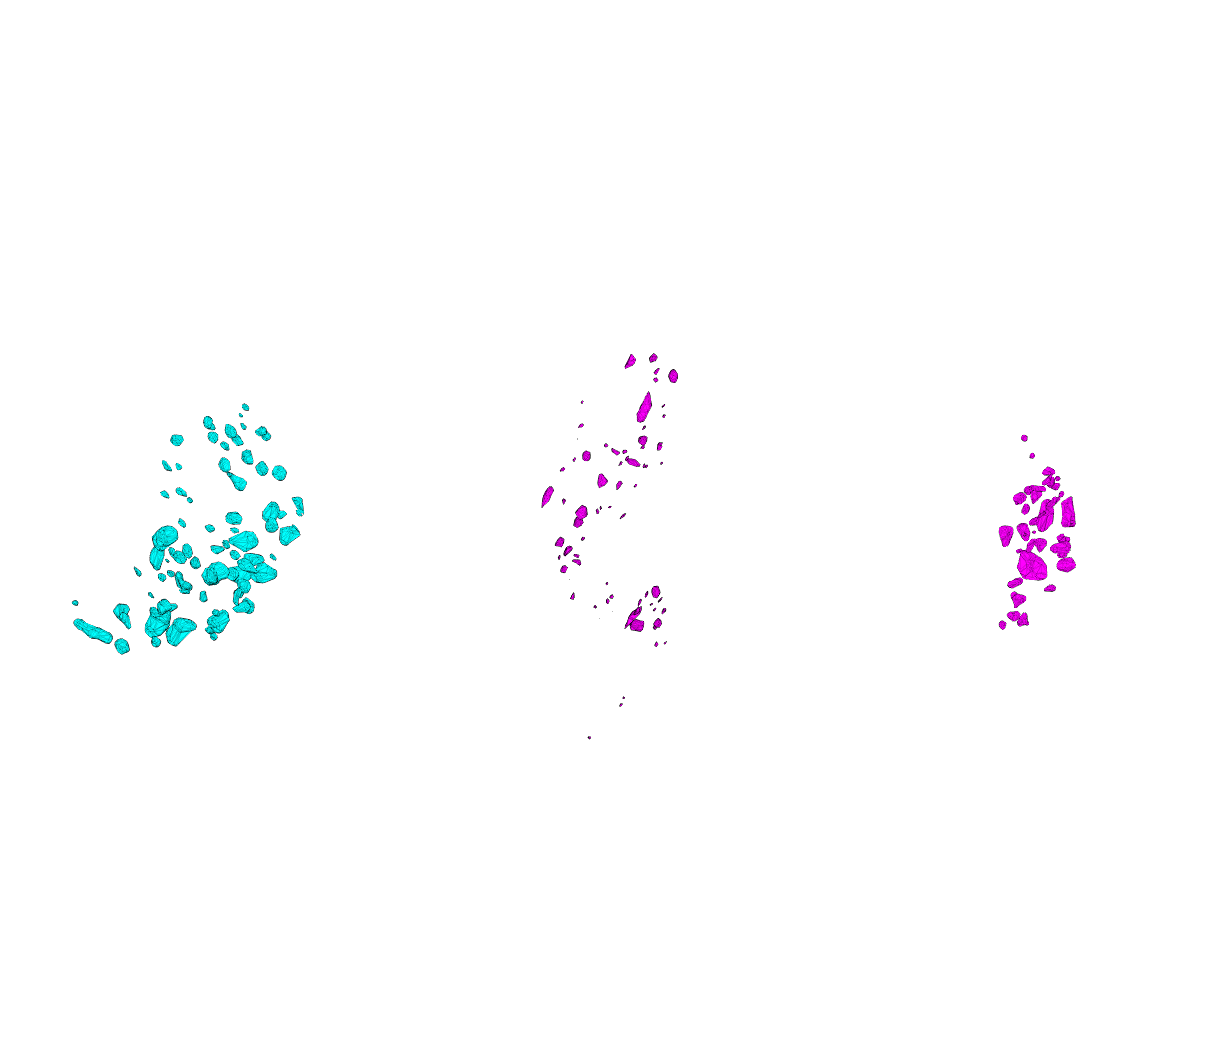

axX =   3×1 Axes array:

  Axes
  Axes
  Axes


axX = plot_lys_alphaSurface(VL,idT,"x")

## Type II Stats

 logical array simplifies analysis

la2 = lysT.Type=="II";

### Healthy II Lysosomes are much smaller than Early Dying II Lysosomes

#### Box Chart

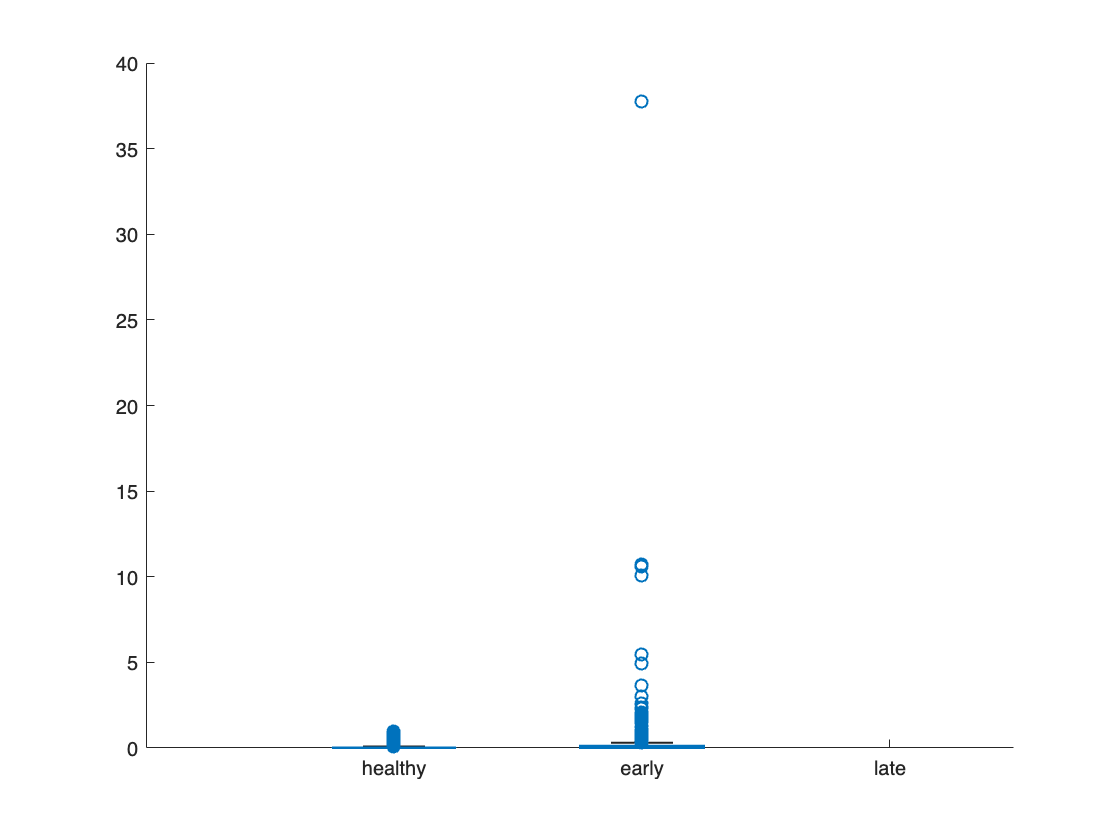

clf
x = lysT.Health(la2);
y = lysT.Volume(la2);

boxchart(x, y)

- Larger range in size

- Not normally distributed

#### Volumes not normally distributed

test for normality shows that lys II volumes are not normally distributed

[h,p] = adtest(lysT.Volume(la2))

h = logical
   1


p =        0.0005


#### Group Summary Type II lysosomes

Mean and Median are significantly lower for healthy lysomes vs early dying

groupsummary(lysT(la2,:),"Health",{'mean','median', 'range', @iqr},"Volume")

ans = 2×6 table
    Health     GroupCount    mean_Volume    median_Volume    range_Volume    fun1_Volume
    _______    __________    ___________    _____________    ____________    ___________

    healthy       803         0.038098        0.0070485         1.0057        0.030617  
    early         697          0.24439         0.020161         39.143         0.11016  


- difference between mean and median shows skew in distribution of data

- Early dying cells have a much larger range in volume than the healthy cells

- Interquartile range large too

#### Healthy Lysosomes Significantly smaller

Ranksum is a Mann-Whitney U-test

x = lysT.Volume(la2 & lysT.Health == "healthy");
y = lysT.Volume(la2 & ~(lysT.Health == "healthy"));

p = ranksum(x,y)

p =    2.4717e-21


## All Cell Types Health Comparison: 

### Late dying cells do not have the largest lysosomes 

Volume order is: late < healthy <  early

#### Late dying lysosomes larger than healthy but smaller than early dying

% lax = lysT.Type == "x";
groupsummary(lysT,"Health",{'mean','median', 'range'},"Volume")

ans = 3×5 table
    Health     GroupCount    mean_Volume    median_Volume    range_Volume
    _______    __________    ___________    _____________    ____________

    healthy       2692        0.076727        0.0090634         22.511   
    early          914         0.22521         0.022573         37.765   
    late           178        0.057866        0.0040862         2.0794   


### Lysosome Volume is significantly different between cell health

using a kruskal wallis analysis

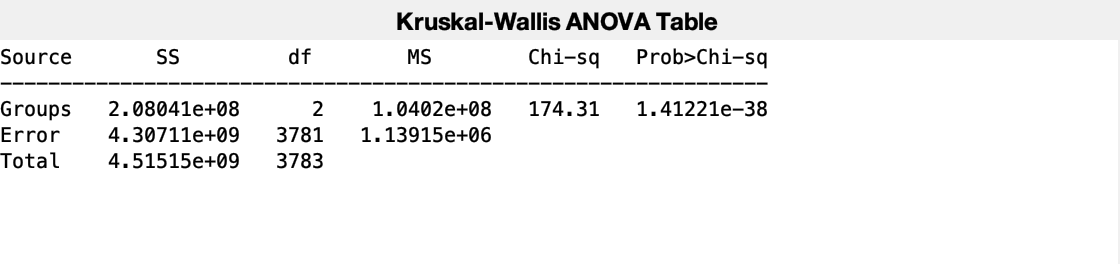

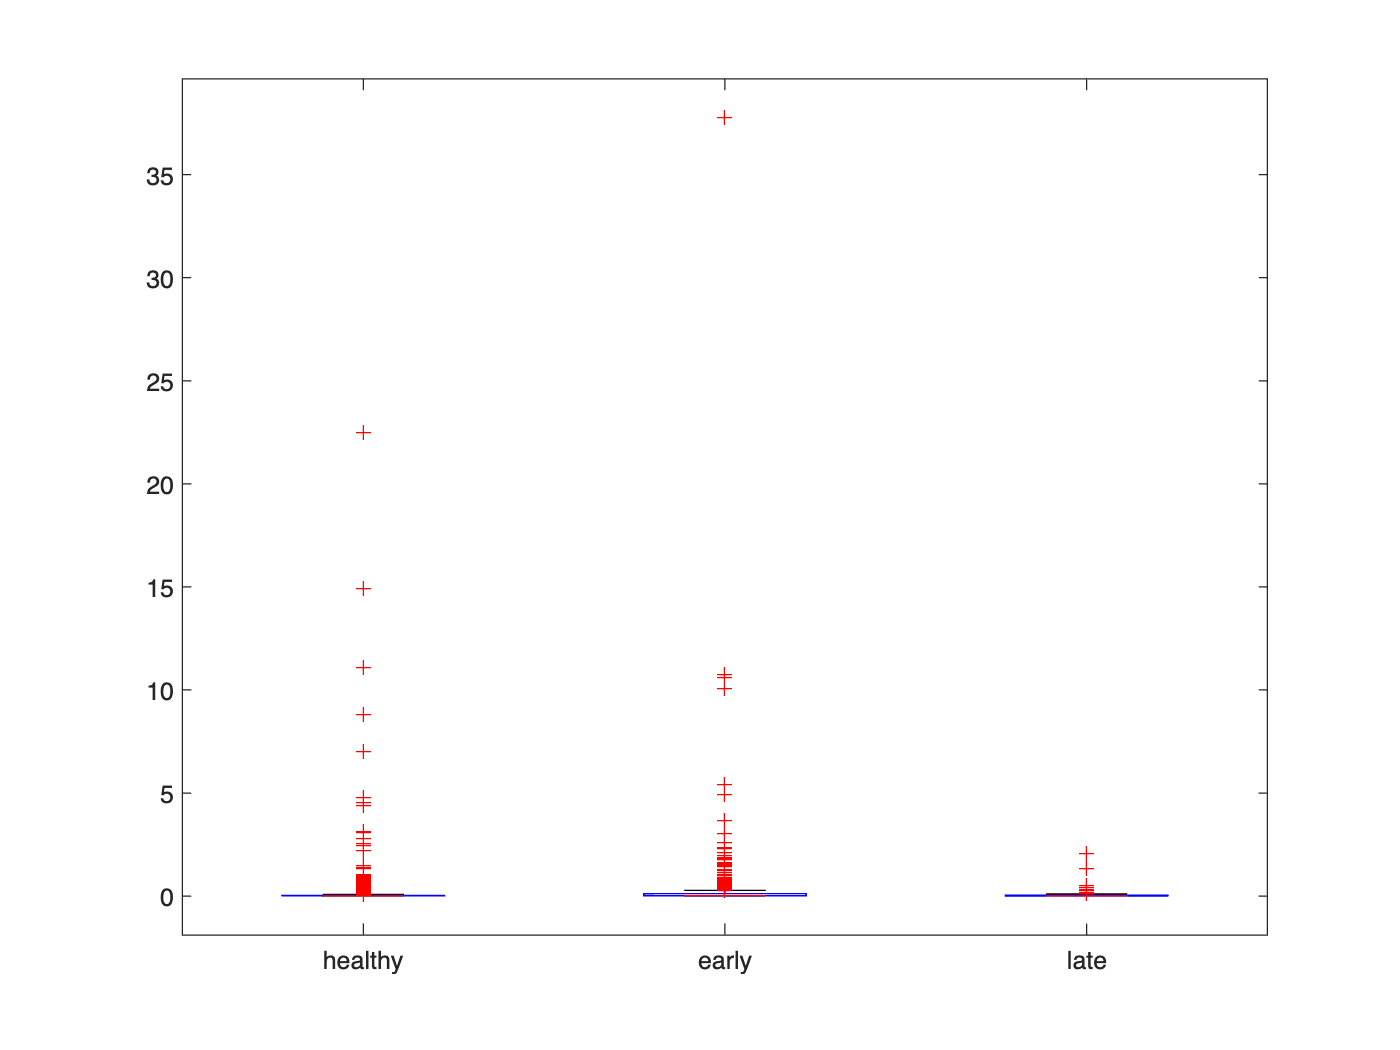

p =    1.4122e-38


tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'  }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[2.0804e+08]}    {[   2]}    {[1.0402e+08]}    {[  174.31]}    {[ 1.4122e-38]}
    {'Error' }    {[4.3071e+09]}    {[3781]}    {[1.1391e+06]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[4.5151e+09]}    {[3783]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {3×1 cell}
            n: [2692 914 178]
       source: 'kruskalwallis'
    meanranks: [1782.3 2294.1 1496.5]
         sumt: 0


y = lysT.Volume;
g = lysT.Health;
[p,tbl,stats] = kruskalwallis(y,g)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


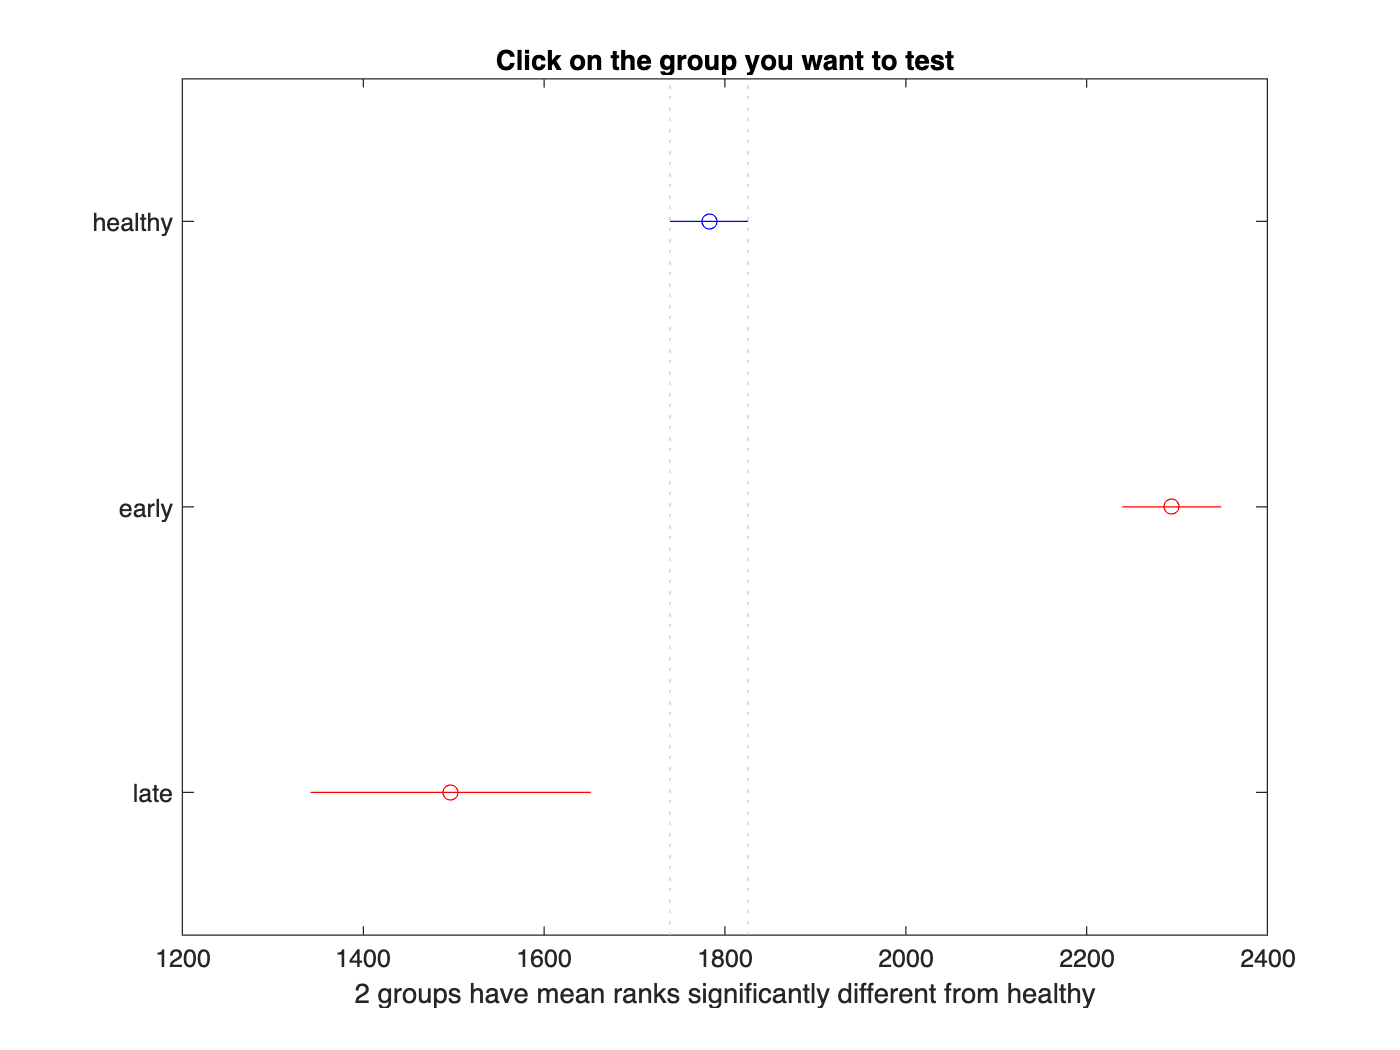

ans =             1            2      -609.84      -511.82       -413.8            0
            1            3       87.707       285.87       484.02    0.0020856
            2            3       587.91       797.68       1007.5   5.5536e-19


multcompare(stats)

## Healthy Cell comparison

Volume Order: III < II < I < IV

lah = lysT.Health == "healthy";
statsHealth = groupsummary(lysT(lah,:),"Type",{'mean','median', 'range', @iqr},"Volume");
statsHealth = sortrows(statsHealth,"median_Volume")

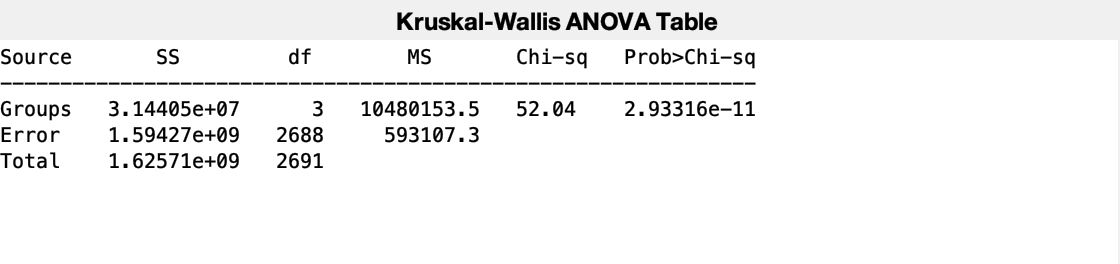

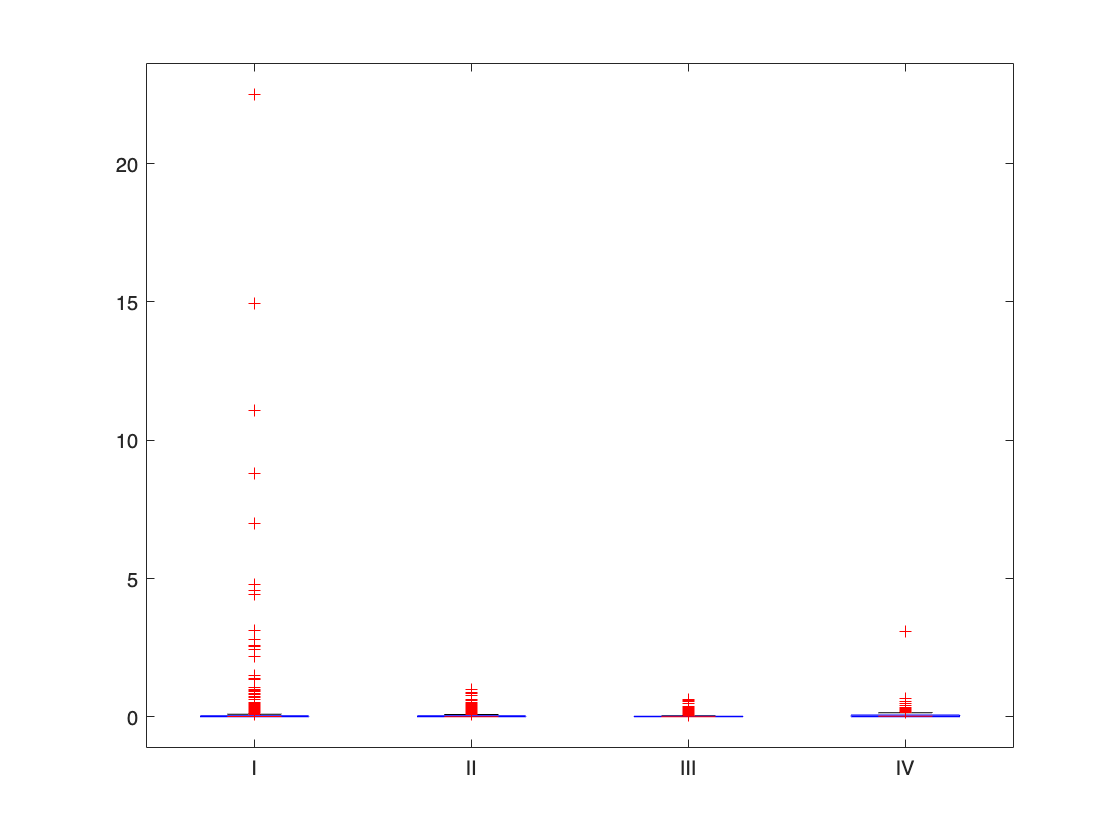

p =    2.9332e-11


tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'  }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[ 3.144e+07]}    {[   3]}    {[ 1.048e+07]}    {[  52.043]}    {[ 2.9332e-11]}
    {'Error' }    {[1.5943e+09]}    {[2688]}    {[5.9311e+05]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[1.6257e+09]}    {[2691]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {4×1 cell}
            n: [774 793 904 221 0]
       source: 'kruskalwallis'
    meanranks: [1419.4 1359.3 1216.2 1578.1 NaN]
         sumt: 0


y = lysT.Volume(lah);
g = lysT.Type(lah);
[p,tbl,stats] = kruskalwallis(y,g)

multcompare(stats)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


## Local Functions

function ax = plot_lys_alphaSurface(VL, idT, type)

fh = mmfig;
fh.Name = sprintf("Type %s",type); 
tiledlayout("flow","TileSpacing","none","Padding","tight");
idc = find(idT.Type==type)';


colorD = dictionary(["healthy" "early" "late"], ["g" "c" "m"]);
ax = gobjects(numel(idc),1);
i = 1;
for m=idc
    
    % [~, vLys, SzLbl] = getVertsFromCellID(VL, idT.Cell(m),1); % align point clouds to axes
    [~, vLys, SzLbl] = getVertsAndAlign(VL, idT.Cell(m),1); % align point clouds to axes


    PC = pointCloud(vLys);
    
    ax(i) = nexttile;
    i = i+1;

    for n=unique(SzLbl)'
    la = SzLbl == n;
    PCselect = select(PC,la);
    if isscalar(unique(PCselect.Location(:,3))) % if just one z slice
        pts = PCselect.Location;
        pts = [pts;...
            pts(:,1:2) pts(:,3)+0.08]; % duplicate points to the next slice to create cylinder
    else
        pts = PCselect.Location;
    end
    shp3d = alphaShape(pts,1); % alpha of 1 most reliable
    plot(shp3d, FaceColor=colorD(idT.Health(m)),EdgeAlpha=0.1,Tag=idT.Cell(m));
    hold on
    axis off
   
    xlim([-10 10])
    ylim([-10 10])
    zlim([-50 50])

    set(gca,CameraTarget=[0,0,0], CameraViewAngle=2)
    end

    fprintf('%d. %s. %s. %1.2f\n', m, idT.Cell(m), idT.Health(m))

end
end